clear all, close all, clc

## Prob-4.1a

Let’s make the combination of probable states

UUU      *DUU     UDU *     **DDU             ***UUD*      **DUD    UDD**       DDD

Accounting for redundancy due to identicality, we have-

UUU      DDU

UUD       DDD

Here, singular states; redundant states

So, system states are:

Operating: UUU

Operating: UUD

Failed: DDU, DDD

## Prob-4.1b

syms lambda mu
L = lambda; m = mu;         % defining symbol

Now, let’s build the state transition diagram

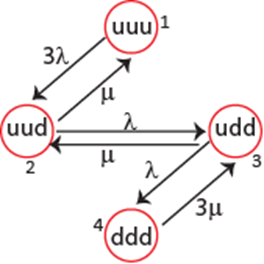

Then, we have the availability matrix like follows-

M_A = [-3*L,  m,     0,     0; ...
       3*L, -(m+L),  mu,    0; ...
       0,    L,     -(L+m), 3*m; ...
       0     0       L     -3*m;]

$$M\_A = \left(\begin{array}{cccc} -3\,\lambda & \mu & 0 & 0\\ 3\,\lambda & -\lambda -\mu & \mu & 0\\ 0 & \lambda & -\lambda -\mu & 3\,\mu \\ 0 & 0 & \lambda & -3\,\mu \end{array}\right)$$

Then, transforming the failed combinations into single row/column, we have-

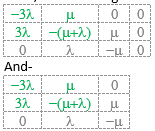

Now, setting 0 in tall the column for failed states, we have the reliability transition matrix-

M_R = [-3*L,  m,     0; ...
       3*L, -(m+L),  0; ...
       0,    L,      0;]

$$M\_R = \left(\begin{array}{ccc} -3\,\lambda & \mu & 0\\ 3\,\lambda & -\lambda -\mu & 0\\ 0 & \lambda & 0 \end{array}\right)$$

## Prob-4.1c

Let's build the matrix to find Eigenvalue


$$S\;\mathit{\mathbf{I}}-\mathit{\mathbf{M}}=0$$


syms s t
I = eye(3);         % identity matrix
E = s*I - M_R       % eigenvalue matrix

$$E = \left(\begin{array}{ccc} 3\,\lambda +s & -\mu & 0\\ -3\,\lambda & \lambda +\mu +s & 0\\ 0 & -\lambda & s \end{array}\right)$$

Now, let's find the determinant and eigenvalues

Dt = det(E);
Dt = simplify(Dt)

$$Dt = s\,\left(3\,\lambda^{2}+4\,\lambda \,s+s^{2}+\mu \,s\right)$$

Now, let's solve it to find the Eigenvector

S = solve(Dt, s)     % solution vector

$$S = \left(\begin{array}{c} 0\\ -2\,\lambda -\frac{\mu }{2}-\frac{\sqrt{4\,\lambda^{2}+8\,\lambda \,\mu +\mu^{2}}}{2}\\ \frac{\sqrt{4\,\lambda^{2}+8\,\lambda \,\mu +\mu^{2}}}{2}-\frac{\mu }{2}-2\,\lambda \end{array}\right)$$

Now, from equation 25, we have-


$$P_n {\left(s\right)}=\frac{cof{{\left(s\bar{I\;} -\bar{\;M} \right)}}_n^T }{\Delta }$$


Here, $\Delta ={\left(s-s_1 \right)}{\left(s-s_2 \right)}\ldots\left(s-s_N \right)$ = Determinant

Now, let's find the P_1(s)-

E_T = transpose(E)          % transpose the eigen matrix

$$E\_T = \left(\begin{array}{ccc} 3\,\lambda +s & -3\,\lambda & 0\\ -\mu & \lambda +\mu +s & -\lambda \\ 0 & 0 & s \end{array}\right)$$

The cofactor function, developed by me, has been attached with the homework-

CF_1 = cofact(E_T, 1,1)     % cofactor of E_T at (1,1)

$$CF\_1 = s\,\left(\lambda +\mu +s\right)$$

P_s1 = CF_1 /Dt 

$$P\_s1 = \frac{\lambda +\mu +s}{3\,\lambda^{2}+4\,\lambda \,s+s^{2}+\mu \,s}$$

Let's expand it-

P_s1 = expand(P_s1)

$$P\_s1 = \frac{\lambda }{3\,\lambda^{2}+4\,\lambda \,s+s^{2}+\mu \,s}+\frac{\mu }{3\,\lambda^{2}+4\,\lambda \,s+s^{2}+\mu \,s}+\frac{s}{3\,\lambda^{2}+4\,\lambda \,s+s^{2}+\mu \,s}$$

Now, to have time-dependent reliability of the system, we make an inverse Laplace transformation,

R_t = ilaplace(P_s1, t)     % t- laplace variable

$$R\_t = {\mathrm{e}}^{-t\,\left(2\,\lambda +\frac{\mu }{2}\right)}\,\left(\cosh\left(t\,\sqrt{\lambda^{2}+2\,\lambda \,\mu +\frac{\mu^{2}}{4}}\right)-\frac{\sinh\left(t\,\sqrt{\lambda^{2}+2\,\lambda \,\mu +\frac{\mu^{2}}{4}}\right)\,\left(\lambda -\frac{\mu }{2}\right)}{\sqrt{\lambda^{2}+2\,\lambda \,\mu +\frac{\mu^{2}}{4}}}\right)$$

Now, let's plot it-

lambda = 1e-2;                  % assumed; h^-1
mu = 0.5*1e-2;                  % assumed
    t0 = 0; tn = 500;           % #input    
t = linspace(t0, tn, 101);     % hours
R_tv = eval(R_t);         % evaluating for L and m

Now,

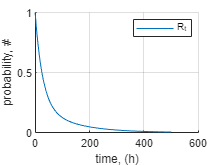

figure()
grid on, hold on
plot(t, R_tv, 'DisplayName', 'R_t')
legend
xlabel('time, (h)')
ylabel('probability, #')

## Prob-4.1d

To find the MTTF, we know-


$$MTTF=\int_0^{\infty } R\left(t\right)dt$$


Let's make it easier assuming simplified values of $\lambda \;$and $\mu \;$

clear t; syms t
lambda = 1e-2;              % h^-1
mu = 0.5e-2;                % 
R_t = eval(R_t);            % evaluating for assumed values

$$R\_t = {\mathrm{e}}^{-\frac{9\,t}{400}}\,\left(\cosh\left(\frac{2069696815548411\,t}{144115188075855872}\right)-\frac{9007199254740992\,\sinh\left(\frac{2069696815548411\,t}{144115188075855872}\right)}{17247473462903425}\right)$$

So, we have-

MTTF = int(R_t, t, 0, inf);
MTTF = double(MTTF)         % hours

MTTF = 50

## Prob-4.2a

Let's define the symbols

syms lambda_1 mu_1  lambda_2 mu_2   lambda_2s
L1 = lambda_1; m1 = mu_1;         % defining symbol
L2 = lambda_2; m2 = mu_2;
L2s = lambda_2s;

The system states are-

Operating: U S

Operating: D U

Operating: U D

Failed:       D D

## Prob-4.2b

Now, the state transition diagram-

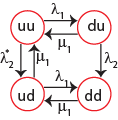     $s^c =4$     s = state types (2, u/d), c = components (2)

So, the availability transition matrix, M_A would be-

M_A = [-(L1+L2s),   m1,         m2,         0;...
        L1,       -(m1+L2),     0           0;...
        L2s,        0,          (-m2+L1),   m1;...
        0,          L2,         L1,        -m1; ]

$$M\_A = \left(\begin{array}{cccc} -\lambda_{1}-\lambda_{\mathrm{2s}} & \mu_{1} & \mu_{2} & 0\\ \lambda_{1} & -\lambda_{2}-\mu_{1} & 0 & 0\\ \lambda_{\mathrm{2s}} & 0 & \lambda_{1}-\mu_{2} & \mu_{1}\\ 0 & \lambda_{2} & \lambda_{1} & -\mu_{1} \end{array}\right)$$

## Prob-4.2c

So, the reliability transition matrix, M_R would be-

M_R = [-(L1+L2s),   m1,         m2,         0;...
        L1,       -(m1+L2),     0           0;...
        L2s,        0,          (-m2+L1),   0;...
        0,          L2,         L1,         0; ]

$$M\_R = \left(\begin{array}{cccc} -\lambda_{1}-\lambda_{\mathrm{2s}} & \mu_{1} & \mu_{2} & 0\\ \lambda_{1} & -\lambda_{2}-\mu_{1} & 0 & 0\\ \lambda_{\mathrm{2s}} & 0 & \lambda_{1}-\mu_{2} & 0\\ 0 & \lambda_{2} & \lambda_{1} & 0 \end{array}\right)$$

## Prob-4.3

Please look up at the other PDF file for 4.3a

###############################

## Functions

This function takes a matrix square-matrix (a) and row and column (er, ec) of an element

Then, returns the minor (a1) and the determinant (d) for that element

function [CF] = cofact(a, er, ec)
    a(:,ec) = nan;       % assign nan to desired r/c
    a(er,:) = nan;
    r = size(a,1);      % rows in the matrix
    r1 = r-1;           % onestep downsizing
    c = size(a,2);      % col' in the mat'
    c1 = c-1;           %   

Now, create  a long vector

        k = 1;      % long-vector index
    for i=1:1:r
        for j=1:1:c
            if isnan(a(i,j))    % check's for nan
                continue        % doesn't assign anything
            else 
                V(k) = a(i,j);
                k = k+1;
            end
        end 
    end 
    V;

Assing long-vector elements to r1$\times \;$c1 matrix again-

        k = 1;
    for i =1:1:r1
        for j=1:1:c1
            a1(i,j) = V(k);
                k = k+1;
        end 
    end 
    a1;                     % the minor
    d = det(a1);            % the determinant
    CF = (-1)^(er + ec) *d; % cofactor of element
end 